clc; clear; close all;

# 2D-FC Solver for Parameterized S-type Patch Demo

f = @(x, y) exp(x.^2 + y.^2)

f = function_handle with value:
    @(x,y)exp(x.^2+y.^2)


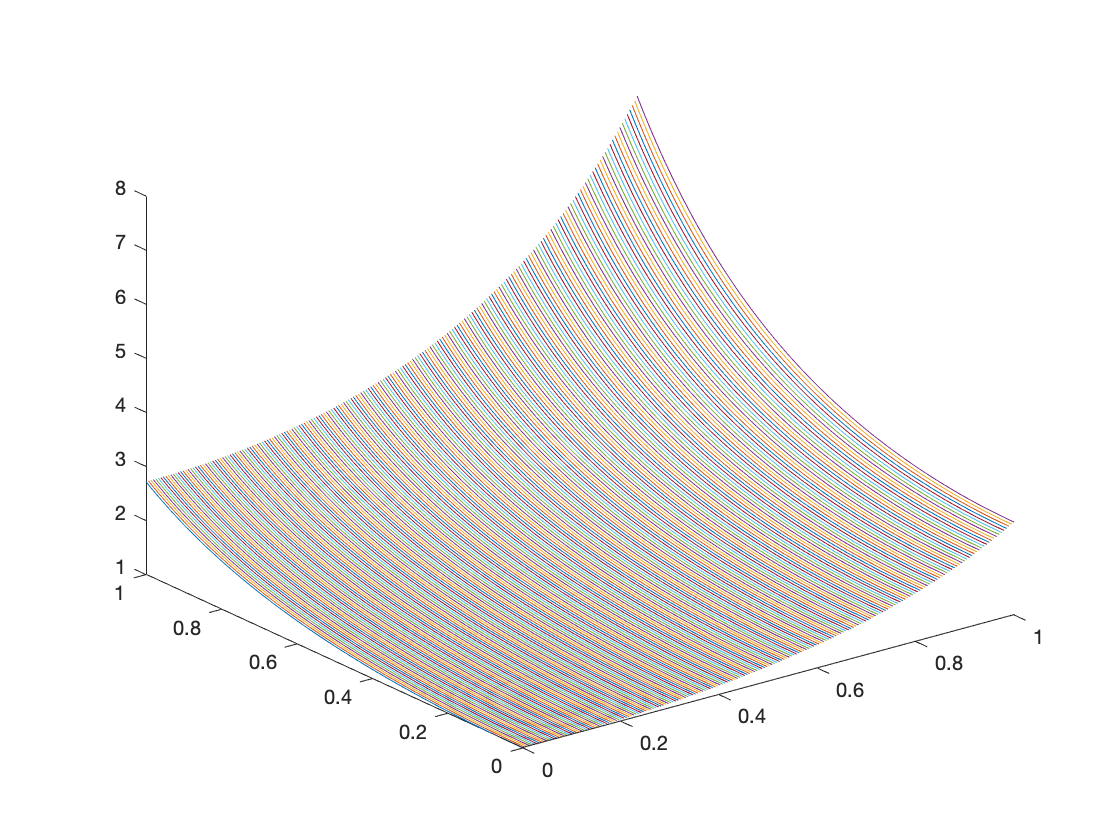


% data given in S-type patch
n = 200;
h = 1./(n-1);
D_mesh = 0:h:1;
C = 27;
d = 10;

[X, Y] = meshgrid(D_mesh);
f_xy = f(X, Y);

figure;
plot3(X, Y, f_xy);


D_mesh_FC = -C*h:h:1;
[X_FC, Y_FC] = meshgrid(D_mesh_FC)

X_FC =    -0.1357   -0.1307   -0.1256   -0.1206   -0.1156   -0.1106   -0.1055   -0.1005   -0.0955   -0.0905   -0.0854   -0.0804   -0.0754   -0.0704   -0.0653   -0.0603   -0.0553   -0.0503   -0.0452   -0.0402   -0.0352   -0.0302   -0.0251   -0.0201   -0.0151   -0.0101   -0.0050         0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055    0.1106
   -0.1357   -0.1307   -0.1256   -0.1206   -0.1156   -0.1106   -0.1055   -0.1005   -0.0955   -0.0905   -0.0854   -0.0804   -0.0754   -0.0704   -0.0653   -0.0603   -0.0553   -0.0503   -0.0452   -0.0402   -0.0352   -0.0302   -0.0251   -0.0201   -0.0151   -0.0101   -0.0050         0    0.0050    0.0101    0.0151    0.0201    0.0251    0.0302    0.0352    0.0402    0.0452    0.0503    0.0553    0.0603    0.0653    0.0704    0.0754    0.0804    0.0854    0.0905    0.0955    0.1005    0.1055  

Y_FC =    -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357   -0.1357
   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307   -0.1307  


load(['FC_data/A_d',num2str(d),'_C', num2str(27), '.mat']);
load(['FC_data/Q_d',num2str(d),'_C', num2str(27), '.mat']);
A = double(A);
Q = double(Q);

fcont = fcont_gram_blend_S(f_xy, d, A, Q)

fcont =    -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000 

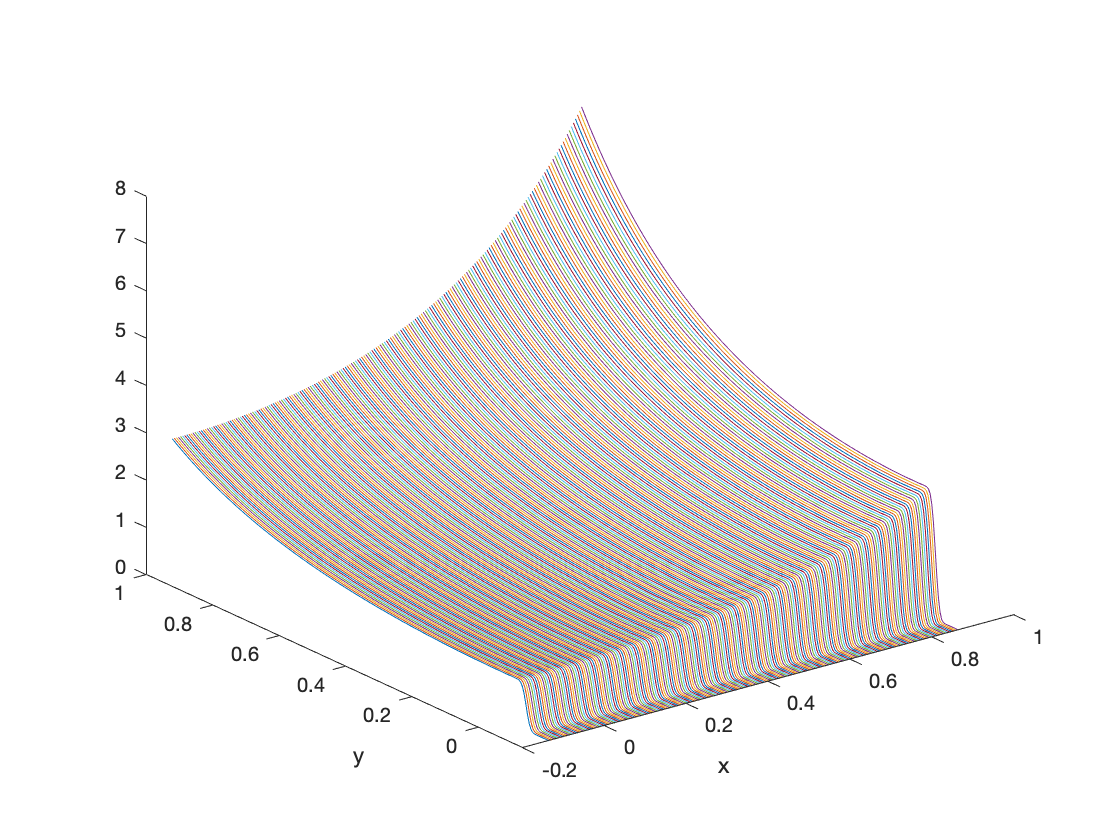


figure;
plot3(X_FC(:, 1:n), Y_FC(:, 1:n), fcont)
xlabel('x')
ylabel('y')